# Mean-Field Phase Space: Iteration Trajs

## first, setup connctivity map

addpath('C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code')
addpath('C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code\Utils')

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);
% mVEpre = mVE; mVIpre = mVI;
% f_EnI0 = MeanFieldEst_BkGd(C_EE,C_EI,C_IE,C_II,...
%                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
%                                    lambda_E,S_Elgn,rE_amb,S_amb,...
%                                    lambda_I,S_Ilgn,rI_amb,...
%                                    gL_E,gL_I,Ve,Vi,mVE,mVI);


## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 0.059; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; S_Ilgn = 0.084; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 
rE_amb = 0.72; rI_amb = 0.36;
T = 2000; sampleT = 2; SimulationT = 1000;


##  For all mV we concern, get corresponding firing rates


mVEtest = 0.45:0.005:0.65;
mVItest = 0.55:0.005:0.75;
f_E_MF = zeros(length(mVEtest),length(mVItest));
f_I_MF = zeros(length(mVEtest),length(mVItest));
% collect neuron ind and connectivity for the center HC
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Mean-Field
for mVEInd = 1:length(mVEtest)
    for mVIInd = 1:length(mVItest)
        f_EnI_Now  = MeanFieldEst_BkGd(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    gL_E,gL_I,Ve,Vi,mVEtest(mVEInd),mVItest(mVIInd));
        f_E_MF(mVEInd,mVIInd) = f_EnI_Now(1);
        f_I_MF(mVEInd,mVIInd) = f_EnI_Now(2);
    end                                                         
end

tic
[f_EnI,meanVs,loop] = MeanFieldEst_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
                                   S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                   lambda_E,S_Elgn,rE_amb,S_amb,...
                                   lambda_I,S_Ilgn,rI_amb,...
                                   tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                   rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                   gL_E,gL_I,Ve,Vi,...
                                   N_HC,n_E_HC,n_I_HC);
toc

历时 0.616731 秒。


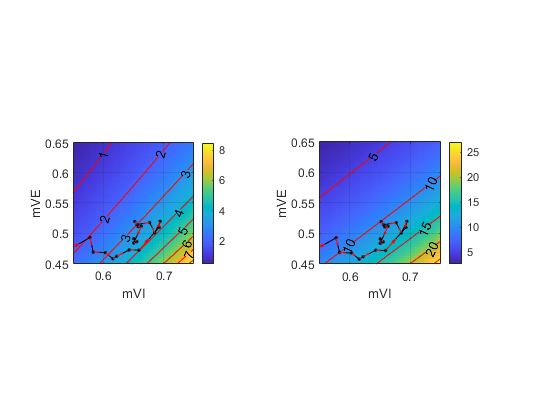


figure(2)
subplot 121
imagesc(mVItest,mVEtest,f_E_MF)
xlabel('mVI'); ylabel('mVE');
set(gca,'YDir','Normal')
colorbar
axis square
hold on
[C1,h1]= contour(mVItest,mVEtest,f_E_MF,'ShowText','on','color','r');
clabel(C1,h1,'FontSize',10,'Color','k')
axis square
plot_dir (meanVs(2,:)', meanVs(1,:)'); % has to be column vectors
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest)])

subplot 122
imagesc(mVItest,mVEtest,f_I_MF)
xlabel('mVI'); ylabel('mVE');
set(gca,'YDir','Normal')
colorbar
axis square
hold on
[C2,h2]= contour(mVItest,mVEtest,f_I_MF,'ShowText','on','color','r');
clabel(C2,h2,'FontSize',10,'Color','k')
axis square
plot_dir (meanVs(2,:)', meanVs(1,:)');
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest)])

tic
[f_EnI,meanVs,loop] = MeanFieldEst_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
                                   S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                   lambda_E,S_Elgn,rE_amb,S_amb,...
                                   lambda_I,S_Ilgn,rI_amb,...
                                   tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                   rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                   gL_E,gL_I,Ve,Vi,...
                                   N_HC,n_E_HC,n_I_HC);
toc

历时 0.565879 秒。


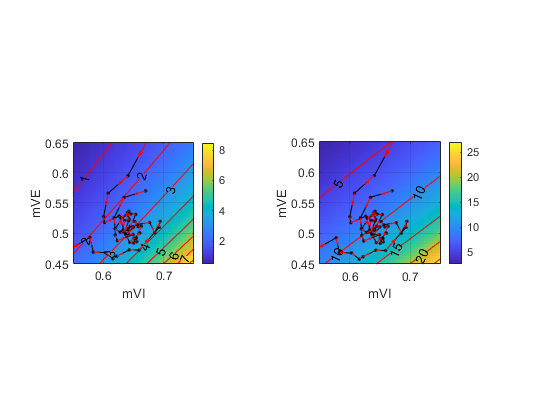

figure(2)
subplot 121
hold on
plot_dir (meanVs(2,:)', meanVs(1,:)'); % has to be column vectors
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest)])

subplot 122
hold on
plot_dir (meanVs(2,:)', meanVs(1,:)');
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest)])